% [pos_x; vel_x; pos_y; vel_y]= [pos_x(k-1)+ vel_x(del_t); pos_y(k-1)+vel_y(del_t); vel_x; vel_y]
bin_size= 15; 
del_t= bin_size;
%state transition F
F= [1 del_t  0 0;
    0 1 0 0;
    0 0 1 del_t;
    0 0 0 1];

% will assume no control input: G=0

% process noise matrix 
Q= 0; %will need to figure out how to compute Q
%initializations

% set estimate uncertainty P to high estimate (as we dont know the initial
% values)



load monkeydata_training.mat

calculate variance pos_x and pos_y

var_handPos= zeros(100, 2);
for i= 1:800
    var_handPos(i,1)= var(trial(i).handPos(1,1:300));
    var_handPos(i,2)= var(trial(i).handPos(2,1:300));
end
var_pos= mean(var_handPos,1)

var_pos =     0.0237    0.0608


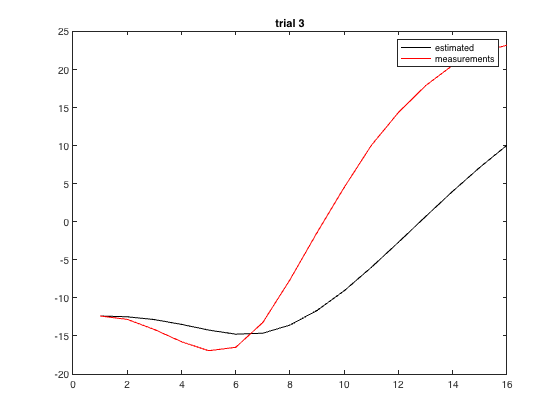

%initializations

% measurement uncertainty matrix R
R= [var_pos(1) 0; 
    0 var_pos(2)];
% R=eye(4);
% observation amtrix H
H= [1 0 0 0;
    0 0 1 0];
N_obs= size(300:bin_size:550-bin_size,2);
% x_pred= zeros(25,4);
x_est= zeros(4,N_obs);
k=2;
% initialize P with high uncertainty value as x_vel and y_vel is unknown
P= eye(4)*500;
figure;
I= eye(size(K*H));
for j= 2:100
    x_0= [trial(j,k).handPos(1,300);0;trial(j,k).handPos(2,300);0]; % can initialize this to starting hand position data, keeping vel_x and vel_y to be zero
    x_est(:,1)= x_0;
    for i= 2:N_obs
        % predict x
        x_est(:,i)= F*x_est(:,i-1);
        % predict P 
        P= F*P*F' + Q;
        
        z= [trial(j,k).handPos(1,300+bin_size*(i-1)); trial(j,k).handPos(2, 300+bin_size*(i-1))];

        %calculate gain
        K= P*H'/(H*P*H' + R);

        %estimate x by computing the error the measured and predicted
        x_est(:, i)= x_est(:,i) + K*(z- H*x_est(:,i));
        % update P
%         P= (I- K*H)*P*(I- K*H)' + K*R*K';
        P= (I- K*H)*P;
    end
%     subplot
    plot(1:N_obs, x_est(1,:), 'Color', 'k');
    hold on; 
    plot(1:N_obs, trial(j,k).handPos(1, 300:bin_size:550-bin_size), 'Color', 'r');
    legend('estimated', 'measurements');
    title("trial "+ j);
    hold off;
end